# HDG scheme to eigenvalues of poisson equation

#### Un método de Galerkin Discontinuo Hibridizable para la ecuación de Schrödinger estacionaria lineal

Resultados preliminares de *@alujan*

clear
format short
syms x y z real

% Let's add to the path the src and drivers: Original Article
addpath('./src/')

% Let's add the path of the gmsh structure: Load Mesh structure
addpath('./mesh/')

## 0. Preliminaries

Load of structures and previous definitions.

#### Load of structures for analisys

Let's load the reference structres we're going to use to set the pilot example

% Importing of a singular structure for first case scenario: Unitary cube
T = load_mesh('L10-cubeD1.msh')

T = struct with fields:
    coordinates: [14×3 double]
       elements: [24×4 double]
      dirichlet: [24×3 double]
        neumann: [0×3 double]
          faces: [60×4 double]
       dirfaces: [37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60]
       neufaces: [1×0 double]
      facebyele: [24×4 double]
    orientation: [24×4 double]
           perm: [24×4 double]
         volume: [24×1 double]
           area: [60×1 double]
        normals: [24×12 double]


% Listing of elements for growth of method testing
listT = {T};

## 1. Construction of the scheme

Definition of the equation and the main elements needed to interact and create the solutions.

#### Definitions of reference solutions

First let's define the values we're going to compare with, in this case the functions $u$ and $\mathit{\mathbf{q}}$, defined for the auxiliar equation, it's important to notice that for instance $\psi$corresponds to the wave function of the particle and $J$ to the complex conjugate of the kinetic momentum operator applied to the wave function

                                               
$$\nabla u\left(\mathit{\mathbf{r}}\right)+\mathit{\mathbf{q}}\left(\mathit{\mathbf{r}}\right)=0\;\textrm{in}\;\Omega$$


                                                    
$$-\textrm{div}\;\mathit{\mathbf{q}}\left(\mathit{\mathbf{r}}\right)=\lambda \;u\left(\mathit{\mathbf{r}}\right)\;\textrm{in}\;\Omega$$


                                                             
$$u\left(\mathit{\mathbf{r}}\right)=0\;\textrm{on}\;\partial \Omega$$


Take in mind this a scalar PDE, for this scenario every evaluation of the values must be in components of the vector.

% Let's define a simple value for U: harmonic vector
% - Characteristics of the oscillator particle
m = 1; omega = 1; hbar = 1;

% - Definition per coordinate of the oscillator
n = 2; Ar = 1 / sqrt(2^n * prod(1:n)) * (m*omega/(pi*hbar))^0.25;
Ur(x) = Ar * exp(-m*omega*(x-10)^2/(2*hbar))*hermiteH(n, sqrt(m*omega/hbar)*(x-10));

% - Caracteristics of the function in space
U(x, y, z) = Ur(x)*Ur(y)*Ur(z); vpa(U, 2)

$$ans(x, y, z) = 0.019\,{\mathrm{e}}^{-0.5\,{\left(x-10.0\right)}^{2}}\,{\mathrm{e}}^{-0.5\,{\left(y-10.0\right)}^{2}}\,{\mathrm{e}}^{-0.5\,{\left(z-10.0\right)}^{2}}\,\left(4.0\,x^{2}-80.0\,x+400.0\right)\,\left(4.0\,y^{2}-80.0\,y+400.0\right)\,\left(4.0\,z^{2}-80.0\,z+400.0\right)$$

% Partial derivarives of the component
Ux = diff(U, x); Uxx = diff(U, x, 2);
Uy = diff(U, y); Uyy = diff(U, y, 2);
Uz = diff(U, z); Uzz = diff(U, z, 2);

Q = -[Ux; Uy; Uz]; vpa(Q, 2)   % Gradient definition

$$ans(x, y, z) = \begin{array}{l} \left(\begin{array}{c} 0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(x-10.0\right)\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(8.0\,x-80.0\right)\,\sigma_{5}\,\sigma_{4}\\ 0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(y-10.0\right)\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(8.0\,y-80.0\right)\,\sigma_{6}\,\sigma_{4}\\ 0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(z-10.0\right)\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(8.0\,z-80.0\right)\,\sigma_{6}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-0.5\,{\left(z-10.0\right)}^{2}}\\ \sigma_{2}={\mathrm{e}}^{-0.5\,{\left(y-10.0\right)}^{2}}\\ \sigma_{3}={\mathrm{e}}^{-0.5\,{\left(x-10.0\right)}^{2}}\\ \sigma_{4}=4.0\,z^{2}-80.0\,z+400.0\\ \sigma_{5}=4.0\,y^{2}-80.0\,y+400.0\\ \sigma_{6}=4.0\,x^{2}-80.0\,x+400.0 \end{array}$$

% Definition of potential taking action
F(x, y, z) = - (Uxx + Uyy +Uzz); vpa(F, 2)

$$ans(x, y, z) = \begin{array}{l} 0.056\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.15\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}\,\sigma_{4}-0.15\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\sigma_{5}\,\sigma_{4}-0.15\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}\,\sigma_{5}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,{\left(x-10.0\right)}^{2}\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,{\left(y-10.0\right)}^{2}\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}-0.019\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,{\left(z-10.0\right)}^{2}\,\sigma_{6}\,\sigma_{5}\,\sigma_{4}+0.037\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(x-10.0\right)\,\left(8.0\,x-80.0\right)\,\sigma_{5}\,\sigma_{4}+0.037\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(y-10.0\right)\,\left(8.0\,y-80.0\right)\,\sigma_{6}\,\sigma_{4}+0.037\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\left(z-10.0\right)\,\left(8.0\,z-80.0\right)\,\sigma_{6}\,\sigma_{5}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-0.5\,{\left(z-10.0\right)}^{2}}\\ \sigma_{2}={\mathrm{e}}^{-0.5\,{\left(y-10.0\right)}^{2}}\\ \sigma_{3}={\mathrm{e}}^{-0.5\,{\left(x-10.0\right)}^{2}}\\ \sigma_{4}=4.0\,z^{2}-80.0\,z+400.0\\ \sigma_{5}=4.0\,y^{2}-80.0\,y+400.0\\ \sigma_{6}=4.0\,x^{2}-80.0\,x+400.0 \end{array}$$

% Processing of functions
u = matlabFunction(U, Vars={x, y, z});

qx = matlabFunction(-Ux, Vars={x, y, z});
qy = matlabFunction(-Uy, Vars={x, y, z});
qz = matlabFunction(-Uz, Vars={x, y, z});

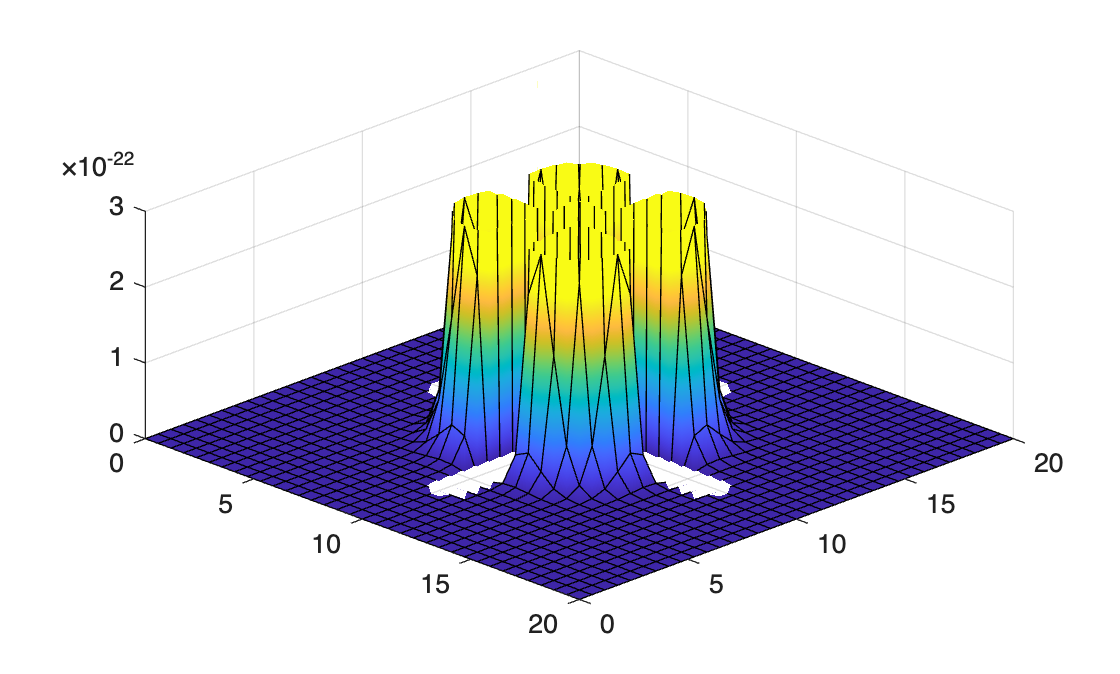

% Validation of dirichlet condition
clf('reset')

% Plot of conditions Null conditions for psi {x, y, z}
fig = figure; theme(fig,"auto");
hold on
fsurf(@(x, y) u( x,  y,  0), [0 20 0 20])     % Condition for z = 0
fsurf(@(x, y) u( x,  y, 20), [0 20 0 20])     % Condition for z = pi
fsurf(@(x, z) u( x,  0,  z), [0 20 0 20])     % Condition for y = 0
fsurf(@(x, z) u( x, 20,  z), [0 20 0 20])     % Condition for y = pi
fsurf(@(y, z) u( 0,  y,  z), [0 20 0 20])     % Condition for x = 0
fsurf(@(y, z) u(20,  y,  z), [0 20 0 20])     % Condition for x = pi

hold off
grid on
view([45, 45])

#### Definition of Cuadrature and Polynomial degrees

Now for the first definitions for the method, we must import the cuadrature that's going to be used, and the polynomial degree that's going to be used for the solution

% It's possible to change the values below to alter the polynomial and
% cuadrature precision for more general viewing
TablesQuadForm3d        % Importing of cuadrature for thetrahedron
TablesQuadForm          % Importing of cuadrature for triangles

k = 1;  % Polynomial Degree

% Switch case for the selection of formulas: cuadratures
switch k
    case 0 
        formulas={tetra3,tetra1,matrix0,matrix4};
    case 1
        formulas={tetra5,tetra3,matrix4,matrix9};
    case 2
        formulas={tetra7,tetra5,matrix9,matrix11};
    case 3
        formulas={tetra9,tetra7,matrix11,matrix14};
    case 4
        formulas={tetra9,tetra9,matrix14,matrix16};
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

#### Norm of solutions for error definitions

The `errorElem `function it's used for this task, the idea used it's comparison with the origin that leaves the norm of elements $\mathit{\mathbf{u}}$and $\mathit{\mathbf{q}}$with known solution


$$|\mathit{\mathbf{p}}-{\mathit{\mathbf{p}}}^* |_{L^2 } \;=|\mathit{\mathbf{p}}|_{L^2 } \;:{\mathit{\mathbf{p}}}^* =0$$


% Error elements definition for display handle
ErrorU      =[];
ErrorQ      =[];
ErrorUhat   =[];
ErrorLambda =[];

ErrorPu   =[];
ErrorPuhat =[];
ErrorUstar =[];
h          =[];

% Norms of unknowns for relative error
Tmax=listT{end};                 % Listing of T elements
Nelts=size(T.elements,1);        % Number of elements enlisted
d3=nchoosek(k+3,3);              % d_i definition of set (cardinality)

## 2. Scheme definition

Definition of the main iteration, mesh elements and bilinear forms

#### HDG: The main iteration

Firstly the method it's created to run in a single run *(presence of one element only)*, with this in mind, when going to expand the idea must be iterated over the different structures

% Definition of the action of tau: Identity
tau = 1*ones(4,Nelts);

% -------------------------------- HDG 3D main function --------------------------------------- %

% Definitions asociated with the tetrahedrization
d2 = nchoosek(k+2,2);    
d3 = nchoosek(k+3,3); 

block3 = @(x) (1+(x-1)*d3):(x*d3);

Nelts  = size(T.elements,1);
Nfaces = size(T.faces,1);
Ndir   = size(T.dirichlet,1);
Nneu   = size(T.neumann,1);

% 4th intervention
% - Faces
face = T.facebyele';                  % 4 x Nelts
face = (face(:)-1)*d2;                % First degree of freedom of each face by element                                               
face = bsxfun(@plus,face,1:d2);       % 4*Nelts x d2 (d.o.f. for each face)                                              
face = reshape(face',4*d2,Nelts);     % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d2);

R_d2 = face(I(:),:); R_d2=reshape(R_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d2 = face(J(:),:); C_d2=reshape(C_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% - Volumes
element = (1:Nelts);                          % Nelts
element = (element(:)-1)*4*d3;                % First degree of freedom of each face by element                                               
element = bsxfun(@plus,element,1:4*d3);       % 4*Nelts x d2 (d.o.f. for each face)                                              
element = reshape(element',4*d3,Nelts);       % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d3); 

R_d3 = element(I(:),:); R_d3 = reshape(R_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d3 = element(J(:),:); C_d3 = reshape(C_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% R_ij^K d.o.f. for local (i,j) d.o.f. in element K ; R_ij^K=C_ji^K
RowsRHS_d2 = reshape(   face,4*d2*Nelts,1);            % Definition of solution shape   
RowsRHS_d3 = reshape(element,4*d3*Nelts,1);              % Definition of solution shape   

% 4th intervention
% Dirichlet faces: defintion
dirfaces = (T.dirfaces(:)-1)*d2;          % First degree of freedom of each face by element
dirfaces = bsxfun(@plus,dirfaces,1:d2);   % Bitwise sum of dirfaces and 1:d2 > dirfaces + 1:d2
dirfaces = reshape(dirfaces',d2*Ndir,1);  % Reshape of dirfaces

% Reduced version of free
free = (1: d2*Nfaces);

% Cleaning of dirfaces: Positions not needed
free(dirfaces) = [];      % Empty of dirfaces positions on free

% Neumann faces: defintion
neufaces = (T.neufaces(:)-1)*d2;          % First degree of freedom of each face by element
neufaces = bsxfun(@plus,neufaces,1:d2);   % Bitwise sum of neufaces and 1:d2 > neufaces + 1:d2
neufaces = reshape(neufaces',d2*Nneu,1);

% Reordering of values find indexes
%indexes = arrayfun(@(i) find(T.facebyele == T.dirfaces(i)), 1:size(T.dirfaces, 2));

% - Map of values indexes
%map = T.orientation(indexes) == -1; T.faces(T.dirfaces(map), [2 3]) = T.faces(T.dirfaces(map), [3 2]);

% Correction of orientation
%T.orientation(indexes) = 1;

Now it's the point to use the local solvers, here are defined the change of basis and the change on the matrices for calculations needed.

% ----------------------------- Local solvers definition function ------------------------------ %

% Computation of the differentials form Matrix: Return in the already desired form

% - Computation of Convection Integrals
[CMx, CMy, CMz] = ConvMatrix(T,k,formulas{1});

% - Computation of the Mass Integrals
Mass = MassMatrix(T,{@(x, y, z) 0*x.*y.*z + 1, ...
                     @(x, y, z) 0.5*m*omega^2*((x - 10).^2 + (y - 10).^2 + (z - 10).^2)}, k,formulas{1});

% - ALR: Reduce this computation into one single line
Mi=Mass{1}; Mv=Mass{2};

% - Computation of Faces Integrals
[tauPP,tauDP,nxDP,nyDP,nzDP,tauDD]=matricesFace(T,tau,k,formulas{3});

Arrays have incompatible sizes for this operation.

Error in matricesFace (line 22)
TauArea=T.area(T.facebyele').*tau;    % 4 x Nelts
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Related documentation


% Condensation of matrices known
nDP = [nxDP, nyDP, nzDP]; divPP = [CMx, CMy, CMz];

% - Matrices defintions: A solvers local
A1=zeros(4*d3,4*d3,Nelts);    % Solver storage reservation
A2=zeros(4*d3,4*d2,Nelts);    % Solver storage reservation
A3=zeros(4*d3,4*d3,Nelts);    % Solver storage reservation
A4=zeros(4*d2,4*d3,Nelts);    % Solver storage reservation

% Matrices related to solvers
% - Definition of the Mass matrix asociated with a_1: 6*d3 x 6*d3
O = zeros(d3,d3,Nelts);   % Big O cero matrix: Shapes juntions

% - Block definition of matrix
Mk = [Mi ,O  ,O   ; ...
      O  ,Mi ,O   ; ...
      O  ,O  ,Mi ];

A1 = [       Mk, -permute(divPP, [2 1 3]); ...
      0.5*divPP,  tauPP + Mv            ];

% - Definition of  the Mass matrix asociated with a_2: 6*d3 x 2*(4*d2)
%   Pendiente la revisión de errores propuesta
A2 = [-permute(nDP  , [2 1 3])  ; ...
       permute(tauDP, [2 1 3]) ];

O = zeros(3*d3,3*d3,Nelts);             % Big O cero matrix: Shapes juntions
Ov = zeros(3*d3,d3,Nelts);

A3_w = [                  Mk,  Ov;....
        permute(Ov, [2 1 3]), Mi];

A3 = [                   O,  Ov;....
      permute(Ov, [2 1 3]), Mi];

O = zeros(d3,d3,Nelts); Ov = [O, O, O]; % Big O cero matrix: Shapes juntions

A4 = [Mk ,permute(Ov, [2, 1, 3]) ; ...
      Ov ,tauPP                 ];

O = zeros(4*d2,d3,Nelts);

A5 = [O, O, O, tauDP];

% Matrices defintions: C solvers Flux
CM = zeros(4*d2,4*d2,Nelts);         % Solver storage reservation
CK = zeros(4*d2,4*d2,Nelts);         % Solver storage reservation

% Operator definition
Q_w_U_w = zeros(4*d3, 4*d3, Nelts);  % Solver operator storage reservation

Q_w     = zeros(4*d3, 4*d3, Nelts);  % Solver Q_w storage reservation
U_w     = zeros(4*d3, 4*d3, Nelts);  % Solver U_w storage reservation

% Parallel creation of flux operators
% Revisión del sistema final a generar
% - Element separation block
block_3d3 = [block3(1) block3(2) block3(3)];

parfor i=1:Nelts            
    CM(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A4(:, :, i)) * (A1(:, :, i) \ A2(:, :, i)) - ...
                A2(:, :, i)' * (A1(:, :, i)' \ A5(:, :, i)') - ...
                A5(:, :, i)  * (A1(:, :, i)  \ A2(:, :, i)) + tauDD(:, :, i);
    CK(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * (A1(:, :, i) \ A2(:, :, i));

    Q_w_U_w(:, :, i) = A1(:, :, i) \ A3_w(:, :, i);
end

% Separation of operators 
U_w(block3(4),block3(4), :) = Q_w_U_w(block3(4), block3(4), :);
Q_w(block_3d3,block_3d3, :) = Q_w_U_w(block_3d3, block_3d3, :);

% Recovery of all elements
M = sparse(R_d2(:),C_d2(:), CM(:)); K = sparse(R_d2(:), C_d2(:),CK(:));

% Boundary conditions evaluation
% The resulting terms are:
%  - uhartD : Reference term evaluation on the Dirichlet faces
%  - qhatN  : Reference term evaluation on the Neumann faces
[etahatD, qhatN] = BC3d(@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,T,k,formulas{3});

% Dirichlet BC: Storage
etahatD=reshape(etahatD,d2*Ndir,1); % uhatD stored as a vector: (2*d2*Ndir) x 1 : todo > Adjust space

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

Etahatv=zeros(d2*Nfaces, 1);        % Storage reservation
Etahatv(dirfaces)=etahatD;          % Uhat stored as a vector: d2*Nfaces
Etahatv(free)    = 1;

% Export of the system
system={M, K, free, dirfaces};
solvers={A1, A2, A3, A4, A5};
Uh=[]; Qxh=[]; Qyh=[]; Qzh=[]; Uhat=[];

% RHS currently has the information of the frontier conditions 
% and the information of inner skeleton: solution of uhat
numEig = 3;

% [Etav_free, lambda] = eigs(M, K, numEig, 1E-5); lambda = diag(lambda)'
[Etav, lambda] = eigs(M, K, numEig, 1E-2); lambda = diag(lambda)'

m * omega^2 * (1^2 + 1/2)

ans =    1.5000e+00


% Reorganization of values
Eta=zeros(d2, Nfaces, numEig);

Uh=zeros(d3,Nelts, numEig);                                 % Reservation of storage

Qxh=zeros(d3,Nelts, numEig);                                % Reservation of storage
Qyh=zeros(d3,Nelts, numEig);                                % Reservation of storage
Qzh=zeros(d3,Nelts, numEig);                                % Reservation of storage

sol = zeros(4*d3, 1);                                       % Temporal reservation of space

maxIter = 0;                                                % Max iterations / distance permitted

% Parallel solution of system: Newton algorithm
parfor N = 1:numEig

    % Reordering of faces
    Eta_n = reshape(Etav(:, N), [d2, Nfaces]);

    % Assignation of variables
    Etav_n = Etav(:, N); %/ inner_Face_L2(T,Eta_n,Eta_n,k,formulas{4});

    % Energies found
    lambda_0 = lambda(N); lambda_n = lambda_0; 

    % Tolerance till convergence
    tolerance = 1E-5; delta_refinement = 1E-3;
    
    scale = 1; delta_lambda = 1; 

    for iter=1:maxIter

        % Reordering of faces
        Eta_n = reshape(Etav_n, [d2, Nfaces]);

        % Normalization of input
        Eta_n = Eta_n / sqrt(inner_Face_L2(T,Eta_n,Eta_n,k,formulas{4}));

        % Computing of Linear form N
        CN_lambda = zeros(4*d2,4*d2,Nelts);      % Solver storage reservation
        CM_lambda = zeros(4*d2,4*d2,Nelts);      % Solver storage reservation

        for i = 1:Nelts
            % Reconstruction of faces bilinear form
            CN_lambda(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i))^2 \ (A1(:, :, i) \ A2(:, :, i)));
            CM_lambda(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i))^1 \ (A1(:, :, i) \ A2(:, :, i)));
        end

        % Proyection into faces form
        N_lambda = sparse(R_d2(:),C_d2(:), CN_lambda(:)); M_lambda = sparse(R_d2(:),C_d2(:), CM_lambda(:));

        % New eta iteration
        Etav_hat = (M - lambda_n * M_lambda) \ N_lambda * Etav_n;

        % Reordering of faces
        Eta_hat = reshape(Etav_hat, [d2, Nfaces]);

        % Normalization of input
        Eta_hat = Eta_hat / sqrt(inner_Face_L2(T,Eta_hat,Eta_hat,k,formulas{4}));

        % Normalization condition
        Eta_L2_norm = inner_Face_L2(T,Eta_hat, Eta_n,k,formulas{4});

        delta_lambda = 1 / Eta_L2_norm;

        % Eta refinement criterion
        if delta_refinement > abs(abs(delta_lambda) - 1)
            scale = abs(lambda_0 - lambda_n)/(lambda_0 - lambda_n) * abs(scale)/2;
        end

        % Update value
        lambda_n_1 = lambda_n + scale * delta_lambda; Etav_n = delta_lambda * Etav_hat;

        % Differences
        epsilon = lambda_n_1 - lambda_n; lambda_n = lambda_n_1;

        % Eta convergence criterion
        if tolerance > abs(abs(delta_lambda) - 1); break; end

    end

    % Update of Eta
    % - Reordering of faces
    Eta_n = reshape(Etav_n, [d2, Nfaces]);% / inner_Face_L2(T,Eta_n,Eta_n,k,formulas{4});

    % - Recover of values per elements
    faces   = T.facebyele'; faces=faces(:);                         % Recovery of faces information
    eta_aux = reshape(Eta_n(:, faces, :),[4*d2, Nelts]);             % Reshape on the faces of Uhat

    % Update of energies
    lambda(N) = lambda_n;

    % Exit variable of parfor
    Eta(:, :, N) = Eta_n;

    % Reconstruction of solution per energy
    for i = 1:Nelts

        % Reconstruction of solution
        sol = A1(:,:,i)\A2(:,:,i) * eta_aux(:,i);

        % Fill of spaces
        % Version pasada:
        % Uh(:,i,N) = eye(d3, 4*d3) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i)) \ sol(:));

        temporal = (eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i)) \ sol(:);

        Uh(:,i,N) = temporal(block3(4));

        Qxh(:,i,N) = sol(block3(1)) + lambda_n * Q_w(block3(1), block3(1), i) * Uh(:,i,N);
        Qyh(:,i,N) = sol(block3(2)) + lambda_n * Q_w(block3(2), block3(2), i) * Uh(:,i,N);
        Qzh(:,i,N) = sol(block3(3)) + lambda_n * Q_w(block3(3), block3(3), i) * Uh(:,i,N);
    end

end

lambda

lambda = 0.9492

### Error comparison with solution

Now we can review our process checking if the error obtained for the process done. Let's check the associated errors.

% Selection of n value to aproximate
lambda_value = 1;

% Norms definitions
normU=errorElem(Tmax,u,zeros(d3,size(Tmax.elements, 1)),k,formulas{1});

normQ=errorElem(Tmax,qx,zeros(d3,size(Tmax.elements, 1)),k,formulas{1})...
     +errorElem(Tmax,qy,zeros(d3,size(Tmax.elements, 1)),k,formulas{1})...
     +errorElem(Tmax,qz,zeros(d3,size(Tmax.elements, 1)),k,formulas{1});

normEta = errorFaces(Tmax,u,zeros(d2,size(Tmax.faces, 1)),k,formulas{4});
    
% Errors with exact solution
error_eta = errorFaces(T,  u, Eta(:, :, lambda_value), k, formulas{4});
error_q   = errorElem (T, qx, Qxh(:, :, lambda_value), k, formulas{1})...
          + errorElem (T, qy, Qyh(:, :, lambda_value), k, formulas{1})...
          + errorElem (T, qz, Qzh(:, :, lambda_value), k, formulas{1});
error_u   = errorElem (T,  u, Uh(:, :, lambda_value), k, formulas{1});

error_eta_ = errorFaces(T,  u, -Eta(:, :, lambda_value), k, formulas{4});
error_q_   = errorElem (T, qx, -Qxh(:, :, lambda_value), k, formulas{1})...
           + errorElem (T, qy, -Qyh(:, :, lambda_value), k, formulas{1})...
           + errorElem (T, qz, -Qzh(:, :, lambda_value), k, formulas{1});
error_u_   = errorElem (T,  u, - Uh(:, :, lambda_value), k, formulas{1});

error_eta = min([error_eta, error_eta_]);
error_u   = min([  error_u,   error_u_]);
error_q   = min([  error_q,   error_q_]);

ErrorQ=[ErrorQ error_q/normQ]

ErrorQ = 0.6787

ErrorU=[ErrorU error_u/normU]

ErrorU = 0.9859

ErrorUhat=[ErrorUhat error_eta/normEta]

ErrorUhat = 0.9461

ErrorLambda = [ErrorLambda abs((hbar * omega^2 * 3/2) - lambda(lambda_value)) / (hbar * omega^2 * 3/2)]

ErrorLambda = 0.3672

% Rate of sucesion: Convergence verification
rateQ      = log2(ErrorQ(1:end-1)./ErrorQ(2:end));
rateU      = log2(ErrorU(1:end-1)./ErrorU(2:end));
rateEta    = log2(ErrorUhat(1:end-1)./ErrorUhat(2:end));
rateLambda = log2(ErrorLambda(1:end-1)./ErrorLambda(2:end));

% Display sequence of values
format bank
disp('Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h');

Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h


disp([rateQ' rateU' rateEta' rateLambda']);
format shortE
disp('Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h');

Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h


disp([ErrorQ' ErrorU' ErrorUhat' ErrorLambda']);

   6.7869e-01   9.8590e-01   9.4610e-01   3.6718e-01



### Solutions visualization

Now let's focus on visualizing our solutions and understanding how it behaves

% Selection of variables
ph = Uh(:, :, 2);

Index in position 3 exceeds array bounds. Index must not exceed 1.

formula = tetra9;

x=T.coordinates(:,1); x=formula(:,1:4)*x(T.elements');
y=T.coordinates(:,2); y=formula(:,1:4)*y(T.elements');
z=T.coordinates(:,3); z=formula(:,1:4)*z(T.elements');
xhat=formula(:,2);
yhat=formula(:,3);
zhat=formula(:,4);

% Translation to polar coordinates


B=dubiner3d(2*xhat-1,2*yhat-1,2*zhat-1,k);
ph=B*ph;

ph = (ph - min(ph(:)))/(max(ph(:)) - min(ph(:)));

xx = x(:); yy = y(:); zz = z(:); ph = ph(:);

map = (abs(ph) < 4E-1) + (abs(ph) > 6E-1); map = map > 0;
%map = ph > 3E-1;

xx = xx(map); yy = yy(map); zz = zz(map); pph = ph(map);

fig = figure; theme(fig,"auto");
scatter3(xx(:), yy(:), zz(:), 10*ones(size(xx(:))), pph(:), 'filled')
colorbar; clim([min(ph(:)), max(ph(:))])
xlabel('x')
ylabel('y')
zlabel('z')

% What's happening on the surface solutions
ph = Eta(:, :, 1); p = u;

formula = formulas{4};

x=T.coordinates(:,1);x=formula(:,[1 2 3])*x(T.faces(:,[1 2 3])');
y=T.coordinates(:,2);y=formula(:,[1 2 3])*y(T.faces(:,[1 2 3])');
z=T.coordinates(:,3);z=formula(:,[1 2 3])*z(T.faces(:,[1 2 3])');
p=p(x,y,z);  %Nnodes x Nfaces
p = (p - min(p(:)))/(max(p(:)) - min(p(:)));
DB=dubiner2d(2*formula(:,2)-1,2*formula(:,3)-1,k);
ph=DB*ph;                        %Nnodes x Nfaces

ph = p; % Change of values

ph = (ph - min(ph(:)))/(max(ph(:)) - min(ph(:)));

xx = x(:); yy = y(:); zz = z(:); ph = ph(:);

map = (abs(ph) < 4E-1) + (abs(ph) > 6E-1); map = map > 0;

xx = xx(map); yy = yy(map); zz = zz(map); ph = ph(map);

fig = figure; theme(fig,"auto");
scatter3(xx(:), yy(:), zz(:), 10*ones(size(xx(:))), ph(:), 'filled')
colorbar; clim([min(ph(:)), max(ph(:))])
xlabel('x')
ylabel('y')
zlabel('z')

%Legacy: Newton applied before
% Insertion of BC
% Etav = zeros(d2*Nfaces, numEig);
% Etav(dirfaces, :) = repmat(etahatD, 1, numEig);
% Etav(free, :)     = Etav_free - M(free,dirfaces)*Etav(dirfaces, :);
% 
% % Reorganization of values
% Eta=zeros(d2, Nfaces, numEig);
% 
% Uh=zeros(d3,Nelts, numEig);                                 % Reservation of storage
% 
% Qxh=zeros(d3,Nelts, numEig);                                % Reservation of storage
% Qyh=zeros(d3,Nelts, numEig);                                % Reservation of storage
% Qzh=zeros(d3,Nelts, numEig);                                % Reservation of storage
% 
% sol = zeros(4*d3, 1);                                       % Temporal reservation of space
% 
% maxIter   = 5;                                             % Max iterations permitted
% max_radii = 0;                                              % Max radii of interest
% 
% % Parallel solution of system: Newton algorithm
% for N = 1:numEig
% 
%     % Reordering of faces
%     Eta_n = reshape(Etav(:, N), [d2, Nfaces]);
% 
%     % Assignation of variables
%     Etav_n = Etav(:, N) / inner_Face_L2(T,Eta_n,Eta_n,k,formulas{4});
% 
%     % Energies found
%     lambda_n = lambda(N);
% 
%     % Tolerance till convergence
%     tolerance = 1E-3; delta_lambda = 1; best_lambda = lambda_n; % Tolerance elements
%     eta_best_iter = Etav_n; best_error = 1;                     % Best error elements
% 
%     scaling_factor = 1;                                         % Scaling factor for refinements
% 
%     for iter=1:maxIter
% 
%         % Reordering of faces
%         Eta_n = reshape(Etav_n, [d2, Nfaces]);
% 
%         % Computing of Linear form N
%         CN_lambda = zeros(4*d2,4*d2,Nelts);      % Solver storage reservation
%         CM_lambda = zeros(4*d2,4*d2,Nelts);      % Solver storage reservation
% 
%         for i = 1:Nelts
%             % Reconstruction of faces bilinear form
%             CN_lambda(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i))^2 \ (A1(:, :, i) \ A2(:, :, i)));
%             CM_lambda(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i))^1 \ (A1(:, :, i) \ A2(:, :, i)));
%         end
% 
%         % Proyection into faces form
%         N_lambda = sparse(R_d2(:),C_d2(:), CN_lambda(:)); M_lambda = sparse(R_d2(:),C_d2(:), CM_lambda(:));
% 
%         % New eta iteration
%         Etav_hat = (M - lambda_n * M_lambda) \ N_lambda * Etav_n;
% 
%         % Reordering of faces
%         Eta_hat = reshape(Etav_hat, [d2, Nfaces]);
% 
%         % Normalization condition
%         delta_lambda = scaling_factor / inner_Face_L2(T,Eta_n,Eta_hat,k,formulas{4});
% 
%         % Update value lambda
%         lambda_n_1 = lambda_n + delta_lambda; 
% 
%         % Differences
%         epsilon = lambda_n_1 - lambda_n; 
% 
%         % Validation of no overlaping between eigenvalues
%         if abs(epsilon) > max_radii
% 
%             % Re-escaling of factor
%             scaling_factor = scaling_factor / 10;
% 
%             % Reevaluation of best values
%             best_lambda = lambda_n; 
%             eta_best_iter = Etav_n;
%             continue
%         end
% 
%         % Update values
%         Etav_n = delta_lambda * Etav_hat; lambda_n = lambda_n_1;
% 
%         % Stop criterion
%         if tolerance > abs(delta_lambda / lambda_n_1); break; end
% 
%         % Best iterator elements
%         if best_error > abs(delta_lambda / lambda_n_1)
%             eta_best_iter = Etav_n; best_error = abs(delta_lambda / lambda_n_1);
%             best_lambda   = lambda_n_1;
%         end
% 
%     end
% 
%     % Update of Eta
%     % - Reordering of faces
%     Eta_n = reshape(eta_best_iter, [d2, Nfaces]);
%     Eta_n = Eta_n / inner_Face_L2(T,Eta_n,Eta_n,k,formulas{4});
% 
%     % - Recover of values per elements
%     faces   = T.facebyele'; faces=faces(:);                         % Recovery of faces information
%     eta_aux = reshape(Eta_n(:, faces, :),[4*d2, Nelts]);             % Reshape on the faces of Uhat
% 
%     % Update of energies
%     lambda(N) = best_lambda;
% 
%     % Exit variable of parfor
%     Eta(:, :, N) = Eta_n;
% 
%     % Reconstruction of solution per energy
%     for i = 1:Nelts
% 
%         % Reconstruction of solution
%         sol = A1(:,:,i)\A2(:,:,i) * eta_aux(:,i);
% 
%         % Fill of spaces
%         % Version pasada:
%         % Uh(:,i,N) = eye(d3, 4*d3) * ((eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i)) \ sol(:));
% 
%         temporal = (eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i)) \ sol(:);
% 
%         Uh(:,i,N) = temporal(block3(4));
% 
%         Qxh(:,i,N) = sol(block3(1)) + lambda_n * Q_w(block3(1), block3(1), i) * Uh(:,i,N);
%         Qyh(:,i,N) = sol(block3(2)) + lambda_n * Q_w(block3(2), block3(2), i) * Uh(:,i,N);
%         Qzh(:,i,N) = sol(block3(3)) + lambda_n * Q_w(block3(3), block3(3), i) * Uh(:,i,N);
%     end
% 
% end